# **CLASSIFICATORE BINARIO (SUPERVISED LEARNING)**

#### **OBBIETTIVO****: *****fornito il dataset da 16 Variabili Indipendenti, predire se il cliente sottoscriverà il nuovo contratto con la banca***** (previsioni di marketing).**

1. **SETUP****: ***Pulizia workspace e command window, aggiunta delle cartelle 'Dataset' e 'Functions', settaggio seed di default per la ripetibilià della predizione.*

2. **DATA IMPORT****:*** Importazione del dataset 'bankfull.csv' (45211x17) sottoforma di table: ****myData (****dataset originale****) data (****dataset di copia delle variabili indipendenti per la sovrascrittura ed elaborazione****).***

3. **PRE-PROCESING**

- ***Missing data**** .Verifica della presenza di dati mancanti.*

 missing_data = ismissing(myData);
 missing_data_sum = sum(sum(missing_data)) % *** NON CI SONO DATI MANCANTI ***

missing_data_sum = 0

- ***Feature scaling****  .Standardizzazione delle feature numeriche.*

-  ***Outliers**** .Verifica della presenza di dati numerici anomali, solo numerici, tramite il metodo 'median' che identifica outliers se i valori sono maggiori di 3 volte M.A.D(Median Absolute Deviation); 'median' e non 'mean' perchè anche se quest'ultimo è più veloce, M.A.D. risulta essere più "robusto". Sostituzione dei dati anomali con il valore non anomalo più vicino ('nearest'), per non alterare troppo negativamente un errore di identificazione.*

%M.A.D.
outlier_day = isoutlier(data.day,'median');
outlier_day_sum_MAD = sum(outlier_day) % *** NON CI SONO OUTLIER IN 'day' ***

outlier_day_sum_MAD = 0

outlier_age = isoutlier(data.age,'median');
outlier_age_sum_MAD = sum(outlier_age)

outlier_age_sum_MAD = 487

outlier_balance = isoutlier(data.balance,'median');
outlier_balance_sum_MAD = sum(outlier_balance)

outlier_balance_sum_MAD = 7079


%SIGMA
outlier_day = isoutlier(data.day,'mean');
outlier_day_sum_MEAN = sum(outlier_day) % *** NON CI SONO OUTLIER IN 'day' ***

outlier_day_sum_MEAN = 0

outlier_age = isoutlier(data.age,'mean');
outlier_age_sum_MEAN = sum(outlier_age)

outlier_age_sum_MEAN = 381

outlier_balance = isoutlier(data.balance,'mean');
outlier_balance_sum_MEAN = sum(outlier_balance)

outlier_balance_sum_MEAN = 745

- ***Categorical****: .Trasformazione dei dati categorici in numerici con algoritmo senza ordinamento e standardizzazione di essi per equiparare i valori. 'encodeCategorical.m' funzione di trasformazione con modifica salvataggio nameValueVariable.nameVariable per salvare tutti i categorici, anche quelli che si ripetono.*

- ***Principal Component Analysis****: .Ridimensionamento del dataset di partenza secondo un ordine di importanza, selezione delle prime 30 componenti che definiscono il 90% dello spazio.*

%Trasformazione dataset from table to array
data_array = table2array(data);
%PCA
class_labels = myData(:,end);
[~, score, ~, ~, explained,~] = pca(data_array);
disp("Le prime 30 dimensioni descrivono il " + sum(explained(1:30)) + "% dello spazio");

Le prime 30 dimensioni descrivono il 90.0528% dello spazio


pcaData = array2table(score(:,1:30));
pcaData(:,end+1) = class_labels;

whos data pcaData

  Name             Size               Bytes  Class    Attributes

  data         45211x51            18458646  table              
  pcaData      45211x31            15751514  table              



4. **DATA PARTITION**: Partizionamento del nuovo dataset in "training_set" e "test_set" con l'algoritmo del '**K-Fold**', k = 5 perchè fra i due valori più usuali (5,10) risulta essere migliore a livello di predizioni corrette (Confusion Matrix).

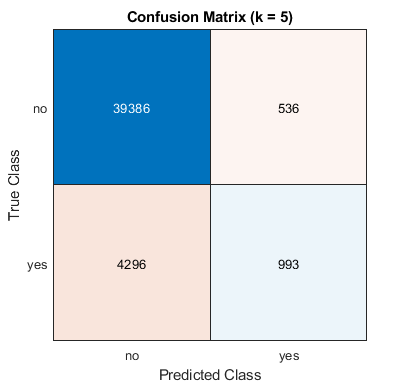

%K-fold, k = 5 -------------------------------------------------------------
 data_partition = cvpartition(num_observation,'kfold',5);
%Model generation, cross validation and predictions ------------------------
%Confusion Matrix ----------------------------------------------------------
 cm = confusionchart(table2cell(pcaData(:,end)),predictions);
 cm.Title = 'Confusion Matrix (k = 5)';

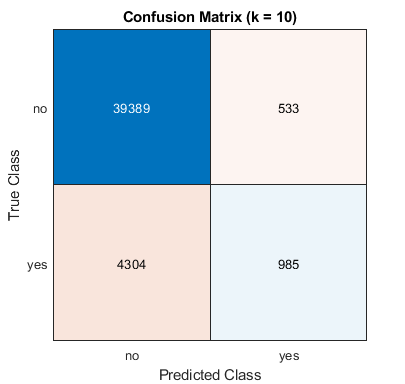

%K-fold, k = 10 ------------------------------------------------------------
 data_partition = cvpartition(num_observation,'kfold',10);
%Model generation, cross validation and predictions ------------------------
%Confusion Matrix ----------------------------------------------------------
 cm = confusionchart(table2cell(pcaData(:,end)),predictions);
 cm.Title = 'Confusion Matrix (k = 10)';

5. **MODEL GENERATION**: *Generazione del modello di classificazione, siccome il dataset è di grandi dimensioni viene utilizzato 'fitclinear' come funzione per la creazione del modello di classificazione (lineare).*

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).
Copying objective function to workers...
Done copying objective function to workers.


|===============================================================================================================|
| Iter | Active  | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Lambda |      Learner |
|      | workers | result |             | runtime     | (observed)  | (estim.)    |              |              |
|===============================================================================================================|
|    1 |       4 | Best   |     0.11698 |      9.1019 |     0.11698 |     0.11698 |      0.87775 |     logistic |


|    2 |       2 | Best   |      0.1069 |       10.42 |      0.1069 |     0.10695 |   0.00036141 |     logistic |
|    3 |       2 | Accept |      0.1069 |      10.097 |      0.1069 |     0.10695 |   1.4348e-08 |     logistic |
|    4 |       2 | Accept |      0.1073 |        11.5 |      0.1069 |     0.10695 |   7.6006e-05 |          svm |


|    5 |       4 | Accept |      0.1069 |      2.7998 |      0.1069 |      0.1069 |   0.00035374 |     logistic |


|    6 |       4 | Accept |      0.1069 |      4.6354 |      0.1069 |     0.10689 |   4.2317e-08 |     logistic |


|    7 |       3 | Accept |     0.10727 |      7.0381 |      0.1069 |     0.10689 |      0.12857 |          svm |
|    8 |       3 | Accept |     0.10727 |       7.109 |      0.1069 |     0.10689 |       0.1773 |          svm |


|    9 |       3 | Best   |     0.10688 |      5.1705 |     0.10688 |     0.10689 |    1.062e-05 |     logistic |


|   10 |       3 | Accept |      0.1073 |      5.6708 |     0.10688 |     0.10689 |   5.9285e-08 |          svm |


|   11 |       3 | Accept |      0.1073 |      6.3946 |     0.10688 |     0.10689 |   2.2123e-10 |          svm |


|   12 |       3 | Accept |      0.1069 |      4.6606 |     0.10688 |     0.10689 |   2.2371e-10 |     logistic |


|   13 |       3 | Accept |      0.1073 |      5.1477 |     0.10688 |     0.10688 |   2.0213e-06 |          svm |


|   14 |       3 | Accept |      0.1069 |      3.5398 |     0.10688 |     0.10688 |   7.6641e-05 |     logistic |


|   15 |       4 | Accept |      0.1069 |      5.4915 |     0.10688 |     0.10688 |   7.8385e-07 |     logistic |


|   16 |       4 | Accept |     0.11698 |      11.698 |     0.10688 |     0.10688 |       2.2093 |          svm |


|   17 |       4 | Accept |      0.1069 |      7.7249 |     0.10688 |     0.10692 |   1.1974e-09 |     logistic |


|   18 |       4 | Accept |      0.1073 |      11.718 |     0.10688 |     0.10692 |    0.0024796 |          svm |


|   19 |       4 | Accept |      0.1073 |      10.613 |     0.10688 |     0.10692 |   2.5388e-09 |          svm |


|   20 |       2 | Accept |      0.1073 |      9.4201 |     0.10688 |     0.10689 |   1.2861e-05 |          svm |
|===============================================================================================================|
| Iter | Active  | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Lambda |      Learner |
|      | workers | result |             | runtime     | (observed)  | (estim.)    |              |              |
|===============================================================================================================|
|   21 |       2 | Accept |      0.1073 |      7.1361 |     0.10688 |     0.10689 |     0.022665 |          svm |
|   22 |       2 | Accept |     0.10708 |      3.0994 |     0.10688 |     0.10689 |    0.0034207 |     logistic |


|   23 |       4 | Accept |      0.1069 |      2.4769 |     0.10688 |     0.10689 |   1.7971e-07 |     logistic |


|   24 |       4 | Accept |     0.10694 |      4.1453 |     0.10688 |      0.1069 |    0.0012066 |     logistic |


|   25 |       2 | Accept |      0.1073 |      6.3345 |     0.10688 |      0.1069 |    0.0016574 |          svm |
|   26 |       2 | Accept |      0.1073 |      7.2231 |     0.10688 |      0.1069 |   2.4343e-05 |          svm |
|   27 |       2 | Accept |      0.1069 |      3.8514 |     0.10688 |      0.1069 |   2.9813e-06 |     logistic |


|   28 |       4 | Accept |      0.1069 |      2.3524 |     0.10688 |      0.1069 |   4.1596e-09 |     logistic |


|   29 |       4 | Accept |      0.1069 |      3.8786 |     0.10688 |     0.10689 |   5.5406e-06 |     logistic |


|   30 |       3 | Accept |      0.1069 |      3.9558 |     0.10688 |     0.10689 |   4.9435e-10 |     logistic |
|   31 |       3 | Accept |      0.1073 |      5.6247 |     0.10688 |     0.10689 |    5.056e-05 |          svm |


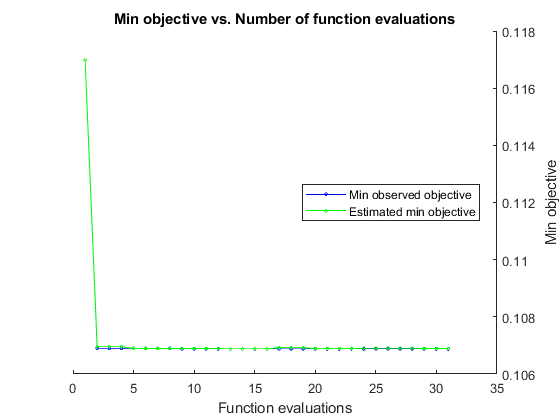

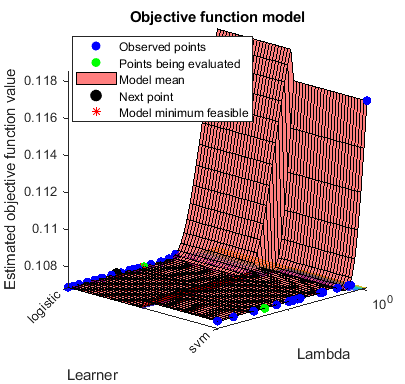


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 31
Total elapsed time: 104.4579 seconds
Total objective function evaluation time: 200.0292

Best observed feasible point:
     Lambda      Learner 
    _________    ________

    1.062e-05    logistic

Observed objective function value = 0.10688
Estimated objective function value = 0.10688
Function evaluation time = 5.1705

Best estimated feasible point (according to models):
      Lambda      Learner 
    __________    ________

    5.5406e-06    logistic

Estimated objective function value = 0.10689
Estimated function evaluation time = 4.7896



%Ottimizzazione classificatore ----------------------------------------------
fitclinear(pcaData,'Var31','OptimizeHyperparameters','auto',...
            'HyperparameterOptimizationOptions', struct('AcquisitionFunctionName',...
            'expected-improvement-plus','UseParallel',true,'CVPartition',data_partition));


%classification_model = fitclinear(pcaData,'Var31','Lambda',1.062e-05,'Learner','logistic',...

6. **CROSS VALIDATION**: *Cross validazione del modello generato, in questo caso non è possibile utilizzare la funzione 'crossval' bensì è possibile generare il modello validato.*

classification_model = fitclinear(pcaData,'Var31','Lambda',1.062e-05,'Learner',...
                      'logistic','CVPartition',data_partition)

classification_model =   ClassificationPartitionedLinear
    CrossValidatedModel: 'Linear'
           ResponseName: 'Var31'
        NumObservations: 45211
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: {'no'  'yes'}
         ScoreTransform: 'none'


  Properties, Methods


7. **PREDICTIONS**:

 predictions = kfoldPredict(classification_model);

8. **CONFUSION MATRIX**:

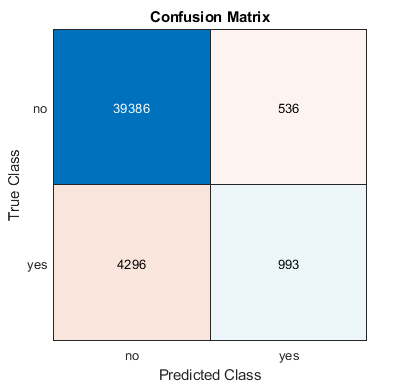

cm = confusionchart(table2cell(pcaData(:,end)),predictions);
cm.Title = 'Confusion Matrix';

 
%Calcolo delle prestazioni -----------------------------------------------
 accuracy    = 100 * sum(diag(cm.NormalizedValues)) / sum(sum(cm.NormalizedValues))

accuracy = 89.3123

 sensitivity = 100 * cm.NormalizedValues(1,1) / sum(cm.NormalizedValues(1,:))

sensitivity = 98.6574

 precision   = 100 * cm.NormalizedValues(1,1) / sum(cm.NormalizedValues(:,1))

precision = 90.1653

 Fmeasure    = (2 * sensitivity * precision) / (sensitivity + precision)

Fmeasure = 94.2204

#### *********************  **VALUTARE L'IMPATTO DELLE SINGOLE FEATURE**  *********************

%Feature selection for classification using neighborhood component analysis (NCA)
out = table2array(class_labels);
mdl = fscnca(data_array,out);

%Feature
VariableNames = (data.Properties.VariableNames)';
disp(VariableNames);

    {'failure.poutcome'   }
    {'other.poutcome'     }
    {'success.poutcome'   }
    {'unknown.poutcome'   }
    {'apr.month'          }
    {'aug.month'          }
    {'dec.month'          }
    {'feb.month'          }
    {'jan.month'          }
    {'jul.month'          }
    {'jun.month'          }
    {'mar.month'          }
    {'may.month'          }
    {'nov.month'          }
    {'oct.month'          }
    {'sep.month'          }
    {'cellular.contact'   }
    {'telephone.contact'  }
    {'unknown.contact'    }
    {'no.loan'            }
    {'yes.loan'           }
    {'no.housing'         }
    {'yes.housing'        }
    {'no.default'         }
    {'yes.default'        }
    {'primary.education'  }
    {'secondary.education'}
    {'tertiary.education' }
    {'unknown.education'  }
    {'divorced.marital'   }
    {'married.marital'    }
    {'single.marital'     }
    {'admin..job'         }
    {'blue-collar.job'    }
    {'entrepreneur.job'   }
    {'housemaid.job'

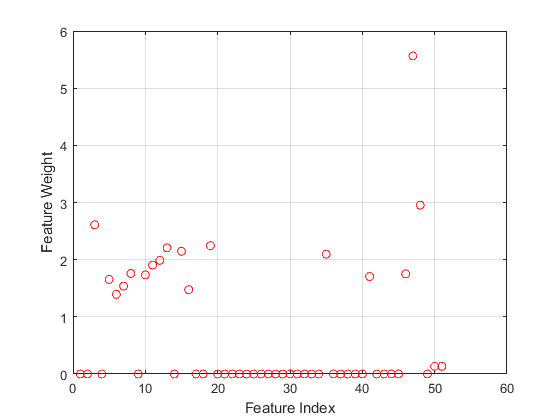

%Plot
figure()
plot(mdl.FeatureWeights,'ro')
xlabel('Feature Index')
ylabel('Feature Weight')
grid on